% Presetting
PosExtract=[0; 0; 0; 1];

% 3-DoF Manipulator Type 2 Forward Kinematics
syms L1 L2 L3 theta1 theta2 theta3;

% Base to Arm1
a0 = 0;
alpha0 = 0;
d1 = L1;
T01 = DHParameter(a0, alpha0, d1, theta1)

$$T01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Arm1 to Arm2
a1 = 0;
alpha1 = sym(pi)/2;
d2 = 0;
T12 = DHParameter(a1, alpha1, d2, theta2)

$$T12 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & 0\\ \frac{4967757600021511\,\sin\left(\theta_{2}\right)}{81129638414606681695789005144064} & \frac{4967757600021511\,\cos\left(\theta_{2}\right)}{81129638414606681695789005144064} & -1 & 0\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & \frac{4967757600021511}{81129638414606681695789005144064} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Arm2 to Arm3
a2 = L2;
alpha2 = 0;
d3 = 0;
T23 = DHParameter(a2, alpha2, d3, theta3)

$$T23 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & L_{2}\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Arm3 to Endpoint
a3 = L3;
alpha3 = 0;
d4 = 0;
theta4 = 0;
T3E = DHParameter(a3, alpha3, d4, theta4)

$$T3E = \left(\begin{array}{cccc} 1 & 0 & 0 & L_{3}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Base to Endpoint
T0E = simplify(T01*T12*T23*T3E)

$$T0E = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{4}+\sigma_{2} & -\sigma_{3}-\sigma_{1} & \sin\left(\theta_{1}\right) & L_{3}\,\left(\sigma_{4}+\sigma_{2}\right)+L_{2}\,\left(\frac{81129638414606676728031405122553\,\cos\left(\theta_{1}-\theta_{2}\right)}{162259276829213363391578010288128}+\frac{81129638414606686663546605165575\,\cos\left(\theta_{1}+\theta_{2}\right)}{162259276829213363391578010288128}\right)\\ \sigma_{3}-\sigma_{1} & \sigma_{4}-\sigma_{2} & -\cos\left(\theta_{1}\right) & L_{3}\,\left(\sigma_{3}-\sigma_{1}\right)+L_{2}\,\left(\frac{81129638414606676728031405122553\,\sin\left(\theta_{1}-\theta_{2}\right)}{162259276829213363391578010288128}+\frac{81129638414606686663546605165575\,\sin\left(\theta_{1}+\theta_{2}\right)}{162259276829213363391578010288128}\right)\\ \sin\left(\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{2}+\theta_{3}\right) & \frac{4967757600021511}{81129638414606681695789005144064} & L_{1}+L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+L_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{81129638414606676728031405122553\,\sin\left(\theta_{2}-\theta_{1}+\theta_{3}\right)}{162259276829213363391578010288128}\\ \sigma_{2}=\frac{81129638414606676728031405122553\,\cos\left(\theta_{2}-\theta_{1}+\theta_{3}\right)}{162259276829213363391578010288128}\\ \sigma_{3}=\frac{81129638414606686663546605165575\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)}{162259276829213363391578010288128}\\ \sigma_{4}=\frac{81129638414606686663546605165575\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)}{162259276829213363391578010288128} \end{array}$$


% Position of Endpoint according to Base Coordinate
p0E=T0E*PosExtract

$$p0E = \left(\begin{array}{c} L_{3}\,\left(\frac{81129638414606686663546605165575\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)}{162259276829213363391578010288128}+\frac{81129638414606676728031405122553\,\cos\left(\theta_{2}-\theta_{1}+\theta_{3}\right)}{162259276829213363391578010288128}\right)+L_{2}\,\left(\frac{81129638414606676728031405122553\,\cos\left(\theta_{1}-\theta_{2}\right)}{162259276829213363391578010288128}+\frac{81129638414606686663546605165575\,\cos\left(\theta_{1}+\theta_{2}\right)}{162259276829213363391578010288128}\right)\\ L_{3}\,\left(\frac{81129638414606686663546605165575\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)}{162259276829213363391578010288128}-\frac{81129638414606676728031405122553\,\sin\left(\theta_{2}-\theta_{1}+\theta_{3}\right)}{162259276829213363391578010288128}\right)+L_{2}\,\left(\frac{81129638414606676728031405122553\,\sin\left(\theta_{1}-\theta_{2}\right)}{162259276829213363391578010288128}+\frac{81129638414606686663546605165575\,\sin\left(\theta_{1}+\theta_{2}\right)}{162259276829213363391578010288128}\right)\\ L_{1}+L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+L_{2}\,\sin\left(\theta_{2}\right)\\ 1 \end{array}\right)$$

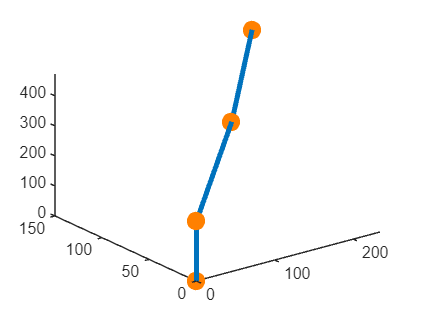

% 3-DoF Manipulator Type 2 Kinematics test by plot graph
theta1=pi/6;
theta2=pi/6;
theta3=pi/6;
L1=200;
L2=200;
L3=200;

% Base to Arm1
a0 = 0;
alpha0 = 0;
d1 = L1;
T01 = DHParameter(a0, alpha0, d1, theta1);

% Arm1 to Arm2
a1 = 0;
alpha1 = pi/2;
d2 = 0;
T12 = DHParameter(a1, alpha1, d2, theta2);

% Arm2 to Arm3
a2 = L2;
alpha2 = 0;
d3 = 0;
T23 = DHParameter(a2, alpha2, d3, theta3);

% Arm3 to Endpoint
a3 = L3;
alpha3 = 0;
d4 = 0;
theta4 = 0;
T3E = DHParameter(a3, alpha3, d4, theta4);

% Base to Each Coordinate
T02 = T01*T12;
T03 = T01*T12*T23;
T0E = T01*T12*T23*T3E;

% Position of Each Coordinate according to Base Coordinate
p01=T01*PosExtract;
p02=T02*PosExtract;
p03=T03*PosExtract;
p0E=T0E*PosExtract;

% plot
p = plot3([PosExtract(1,1), p02(1,1), p03(1,1), p0E(1,1)], [PosExtract(2,1), p02(2,1), p03(2,1), p0E(2,1)], [PosExtract(3,1), p02(3,1), p03(3,1), p0E(3,1)],'-o','LineWidth',3);
p.MarkerFaceColor = [1 0.5 0];
p.MarkerSize = 8;
p.MarkerEdgeColor = [1 0.5 0];